## Qr Algorithm

the QR algorithm is a very impoprtant algorthm that allows us to find a Schur decomposition of a given matrix A, and consequently we can find it's eigenvalues.

We will give a series of implementations for solving this problem.

### Simple QR Algorithm:

In this implementation we will see the easisest way to implement this algorithm, that is in a series of product using the result of the **QR decomposition algorithm**

format short
%Simple QR algorithm
A = Generate_Large_Matrix(5);
tic
A = Simple_QR(A,50);
toc

Elapsed time is 0.007412 seconds.


A

A =     5.0000    0.4803    0.4357    0.7799    8.9660
   -0.0000    4.0000   -0.6399   -2.1340    5.1422
   -0.0000    0.0000    3.0000    0.3841    3.9490
    0.0000    0.0000    0.0000    2.0000   -2.3775
   -0.0000    0.0000    0.0000    0.0000    1.0000


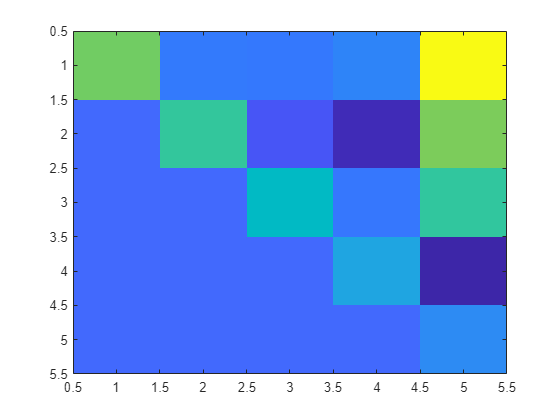

imagesc(A)

This implementation is slow in convergence and it requires a loat of iteration for the computation of the **QR decomposition, **we can try to speed this up.

### Hessenberg Reduction

Using as imput a matrix in the Hessenber form we can reduce the time it takes to compute the QR algorithm.

%Hessemberg reduction and simple QR algorithm
A = Generate_Large_Matrix(5);
H = Hessenberg_reduction(A);
tic
H = Simple_QR(H, 50);
toc

Elapsed time is 0.002229 seconds.


H

H =     5.0000   -0.6674    3.2129    2.8905   -6.0414
    0.0000    4.0000   -0.6054    2.6041    0.6704
   -0.0000    0.0000    3.0000    0.2399   -0.7867
   -0.0000    0.0000    0.0000    2.0000    0.5446
    0.0000   -0.0000    0.0000   -0.0000    1.0000


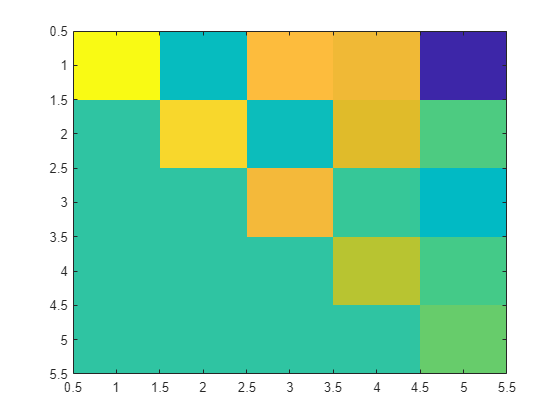

imagesc(H)

%Simple QR algorithm with qr factorization from mathlab
A = Generate_Large_Matrix(5);
tic
A = Simple_QR_mathlab(A,50);
toc

Elapsed time is 0.002086 seconds.


A

A =     5.0000    0.1013   -0.4987    0.5197    4.6142
   -0.0000    4.0000   -0.3484    0.6132    9.0825
   -0.0000    0.0000    3.0000   -0.4184   -4.9633
   -0.0000    0.0000    0.0000    2.0000    4.2855
    0.0000   -0.0000    0.0000   -0.0000    1.0000


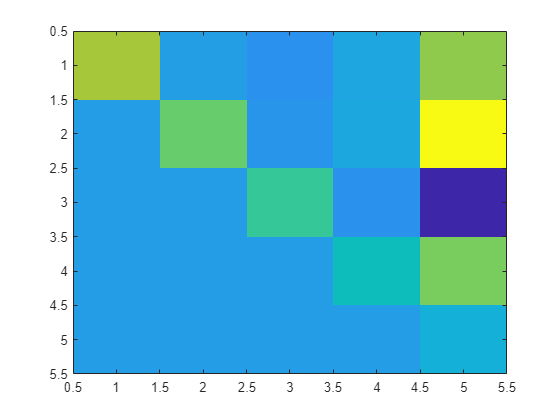

imagesc(A)

%Hessemberg reduction and simple QR algorithm with qr factorization from mathlab
A = Generate_Large_Matrix(5);
H = Hessenberg_reduction(A);
tic
H = Simple_QR(H, 50);
toc

Elapsed time is 0.004008 seconds.


H

H =     5.0000    0.2555   -0.9301   -1.6884   -0.7552
    0.0000    4.0000   -2.4384   -0.1219    4.5592
   -0.0000    0.0000    3.0000   -0.1589   -1.2880
   -0.0000    0.0000    0.0000    2.0000   -0.1274
    0.0000   -0.0000    0.0000   -0.0000    1.0000


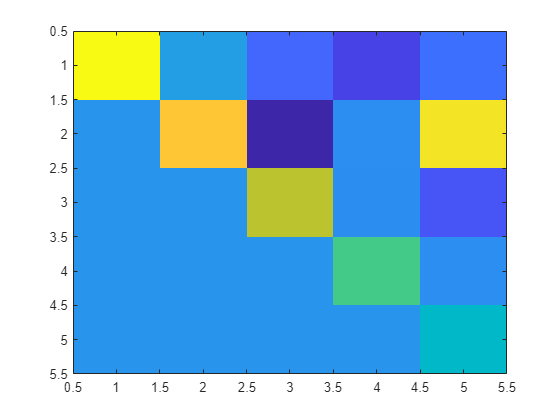

imagesc(H)

### Unshifted QR

In the previous section we still used the basic QR Algorithm, now we will try to incorporate the givens rotation to annichilate the element under the main diagonal during the QR step.

%Unhifted QR factorization
A = Generate_Large_Matrix(9);
A = Hessenberg_reduction(A);
tic
A = Unshifted_QR(A,100);
toc

Elapsed time is 0.009482 seconds.


A

A =     9.0000    0.2608    0.7692    0.4801   -2.1130    0.2050    6.2988    1.3511    8.5157
    0.0000    8.0000   -0.0093    0.4246    1.1154   -1.3880    2.1523    2.7081    0.3977
   -0.0000    0.0000    7.0000   -0.1704   -1.1880    0.7094    1.7782    0.5547   -3.0451
    0.0000   -0.0000    0.0000    6.0000   -0.8636    0.7108   -0.6335   -1.9177    3.8723
   -0.0000    0.0000         0    0.0000    5.0000   -0.3938   -0.4067   -0.2757    0.0040
   -0.0000    0.0000         0         0    0.0000    4.0000   -0.3863    0.2276    6.3252
    0.0000   -0.0000         0         0    0.0000    0.0000    3.0000    0.2538    0.0362
   -0.0000   -0.0000         0         0   -0.0000         0    0.0000    2.0000   -0.4834
    0.0000   -0.0000         0         0    0.0000         0   -0.0000   -0.0000    1.0000


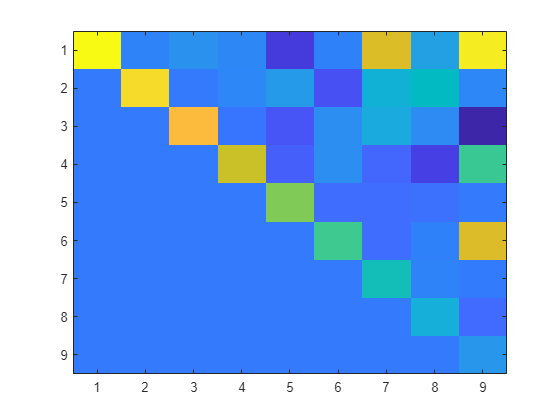

imagesc(A)

### Shift and deflation

We can still speed up this by incorporating some spectral shift with a deflation step

%Shifted QR factorization
A = Generate_Large_Matrix(9);
H = Hessenberg_reduction(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.002182 seconds.


H

H =     9.0000   -4.7472    1.2865   -4.0848   -0.8513   -1.9169   -3.0307   -1.2402   65.7812
    0.0000    1.0000    0.9755   -0.4568    0.1756    2.5672    6.0588   -1.8455   29.7353
    0.0000   -0.0000    8.0000    2.9457    1.1382    2.0027   -0.4715   -0.2235   40.7515
    0.0000   -0.0000   -0.0000    2.0000   -0.2195   -3.4458   -0.5704   -0.3464  -27.5627
   -0.0000   -0.0000    0.0000    0.0000    3.0000    2.7095   -8.1783    1.2067   43.5147
   -0.0000    0.0000    0.0000    0.0000   -0.0000    4.0000    0.0743    2.1083  -14.3680
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    5.0000    1.0249    1.2869
    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    7.0000   -3.1299
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    6.0000


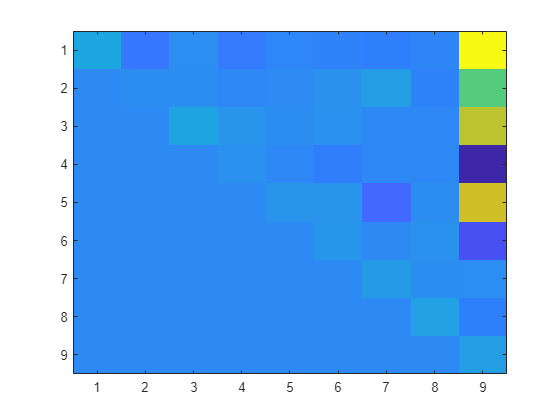

imagesc(H)

And with complex numbers

%Shifted QR factorization
%Complex numbers
N = 8;
cMatrix = complex(rand(N, N), rand(N,N));
idx = randperm(N,3);
cMatrix(idx(1),:) = cMatrix(idx(2),:) + rand * cMatrix(idx(3),:);
rank(cMatrix)

ans = 7

H = Hessenberg_reduction(cMatrix);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.001656 seconds.


H

H =    1.8734 + 1.7339i   1.1602 + 0.7394i   0.1584 - 0.5116i   1.2542 - 0.2089i  -0.2033 + 0.5189i   0.2529 + 0.2349i   0.0382 + 0.0319i   0.1380 + 0.1468i
  -0.0000 + 0.0000i  -1.0452 + 0.9173i   0.5671 - 0.7825i   0.6619 + 0.2551i  -0.0635 - 0.2209i  -0.1481 + 0.0421i  -0.1350 - 0.2241i  -0.1882 + 0.2707i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.3555 - 0.5726i  -0.1874 + 0.0184i   0.2446 + 0.1629i  -0.0949 + 0.0473i   0.1352 - 0.0129i   0.1746 + 0.1602i
   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.1461 + 0.6021i   0.0459 + 0.5086i   0.1932 - 0.1389i   0.0826 - 0.3036i  -0.3461 - 0.0871i
   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2030 + 0.1334i  -0.1056 + 0.1744i   0.1321 + 0.0234i   0.0428 + 0.1558i
   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0076 - 0.0263i  -0.0430 - 0.1079i  -0.0763 - 0.1017i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  

### Householder hessenberg reduction and Francis Method (Chase the bulge)

A = Generate_Large_Matrix(9);
H = Householder_hessenberg(A);
tic
H = CHASE_THE_BULGE(H);
toc

Elapsed time is 0.003456 seconds.


H

H =     1.0000   -0.1071    0.2888    0.2935    8.8572   -2.5047   -2.1999   -8.4622   -8.0171
         0    2.0127    7.0093    2.6804   -5.2814   -5.5459   -5.8488    8.2372   -5.6017
   -0.0000    0.0126    8.9873    2.4514   -1.3010   -7.2389   -1.2680    7.0550   -1.3781
    0.0000   -0.0000         0    3.0000    2.4158   -0.2109    2.4004   -1.8260   -1.0559
    0.0000   -0.0000         0         0    8.0000   -1.8021    1.5248   -1.6729    0.1894
   -0.0000    0.0000   -0.0000         0         0    4.0000    0.8538    0.7556   -0.2508
   -0.0000   -0.0000         0    0.0000   -0.0000         0    6.0000    0.2364   -0.6915
   -0.0000   -0.0000         0    0.0000    0.0000    0.0000         0    5.0097   -0.1398
   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.1385    6.9903


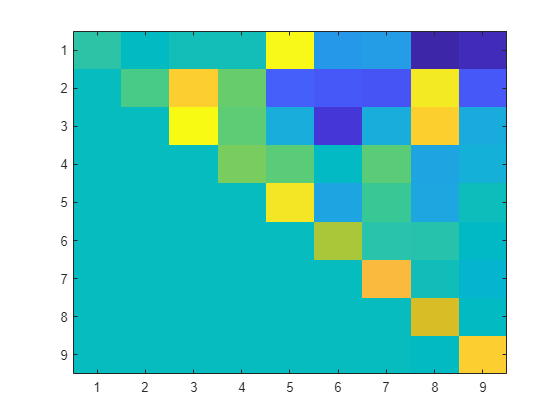

imagesc(H)

## Test Con matrici "Grandi"

A = Generate_Large_Matrix(50);
tic
A = Simple_QR(A,500);
toc

Elapsed time is 0.207596 seconds.


A

A =    50.0000    0.1314   -0.0521   -0.0351    0.9417   -0.0335    0.5121    1.7787    0.1915    1.2192    0.1158   -2.7930    0.8224   -0.6730    0.6780    4.3566    4.2315    3.2550   -0.4305   -9.1401   -2.7807    2.2255    1.0690    2.4726    3.1588   -1.4948   10.3252   -2.4293   -3.6053  -17.5704   -0.7388  -13.6148    4.4517   -7.9865    6.8480   -6.6391  -25.8164   -5.0413  -19.0943  -19.0230  -21.3195  -19.1756   17.4506    2.3372   -4.4554  -10.4880  -33.1231   29.7729   25.8472   66.5986
   -0.0000   49.0000    0.0422    1.0057    0.1374    0.3028   -0.7821    0.5803   -2.1723    1.1926   -2.3439   -1.6712   -2.6456   -2.2668   -0.1361   -2.3835   -3.7699    0.9318   -0.3834    7.3514    1.2294   -2.5414    1.6433   -2.3128    2.7627   -1.7831    7.0136   -0.9664    0.2458   -4.1705    5.9355    0.0505    6.9665    4.3010    6.7187  -14.8612   -2.8067  -11.2251  -19.7176    5.8625    2.7377  -11.9124   28.1234  -30.6304   18.9753  -27.7546   -8.0829   24.2157    6.3491  -20

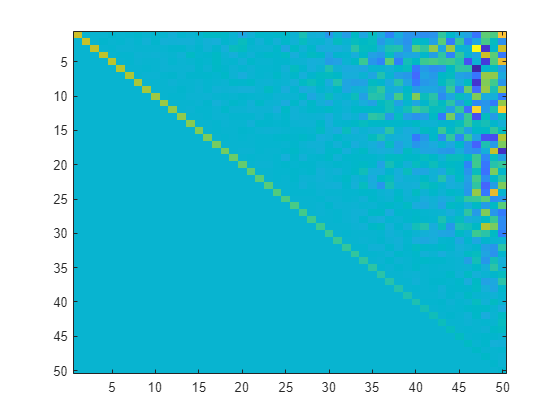

imagesc(A)

A = Generate_Large_Matrix(50);
H = Hessenberg_reduction(A);
tic
H = Unshifted_QR(H,1000);
toc

Elapsed time is 0.313110 seconds.


disp(H);

  Columns 1 through 22

   50.0000    0.0579   -0.2262    0.4215   -0.0826   -0.3175    0.0515   -0.1879   -2.3263    0.1424    2.5569   -0.7109   -0.9749   -0.2107    2.1347    5.7613   -3.5656    1.4463   -0.6840    0.9870   -6.3951   -2.8382
    0.0000   49.0000    0.0757   -0.2475    0.7550    0.6104   -0.6265   -0.7868    1.1811    2.3613    0.3434   -1.3764   -1.0887   -1.5795   -3.4622    0.3291    2.8365   -0.9241   -1.8765   -1.1858  -11.2843    3.5840
    0.0000    0.0000   48.0000   -0.0606   -0.7053    0.7028   -0.2527    0.5652   -1.3394   -0.2554    0.4058   -0.6180   -1.7289   -0.7661   -2.9288   -1.9324    2.4429   -0.3474    1.1218   -1.4522    2.4912   -2.5505
   -0.0000    0.0000    0.0000   47.0000    0.0059   -0.3619    0.0729   -0.2172   -1.0652    2.8123    0.0927   -0.8425   -0.4233   -1.5185    5.0316   -1.9774   -1.0735   -1.9552   -2.4931   -0.9283   -5.6681    2.9532
    0.0000   -0.0000    0.0000    0.0000   46.0000   -0.1969   -0.3934    0.3953    0.6398  

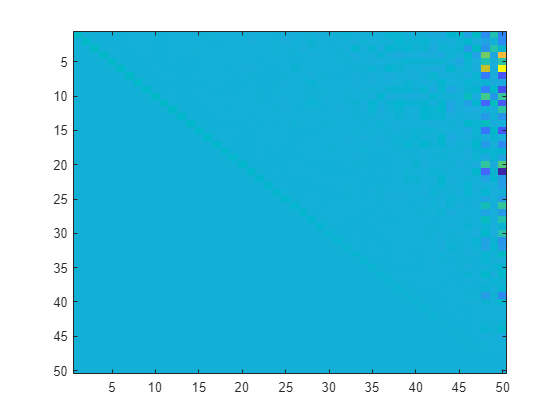

imagesc(H)

A = Generate_Large_Matrix(50);
H = Hessenberg_reduction(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.012271 seconds.


H

H = 1.0e+03 *

    0.0500    0.0002    0.0000   -0.0003    0.0004    0.0005    0.0005    0.0007   -0.0043   -0.0001    0.0001    0.0017   -0.0006    0.0008   -0.0004    0.0044   -0.0016   -0.0061    0.0024    0.0029    0.0113    0.0030   -0.0047   -0.0009   -0.0042    0.0001   -0.0019   -0.0014    0.0142    0.0110    0.0011   -0.0016   -0.0061   -0.0343    0.0093   -0.0141    0.0194    0.0074    0.0072   -0.0135    0.0185    0.0068   -0.0052   -0.0374    0.0764    0.0717    0.0681    0.0498    0.2359   -0.0950
   -0.0000    0.0490    0.0000    0.0001   -0.0001    0.0010   -0.0002   -0.0005    0.0017   -0.0002   -0.0017   -0.0036    0.0003   -0.0003   -0.0008    0.0044    0.0022    0.0051    0.0014    0.0003    0.0001   -0.0100   -0.0003    0.0050   -0.0039    0.0002   -0.0067    0.0083   -0.0008    0.0020   -0.0002   -0.0090    0.0039   -0.0072    0.0024   -0.0027    0.0053   -0.0093    0.0149   -0.0080    0.0281    0.0061    0.0055   -0.0271    0.0665   -0.0736   -0.0119    0.0141    

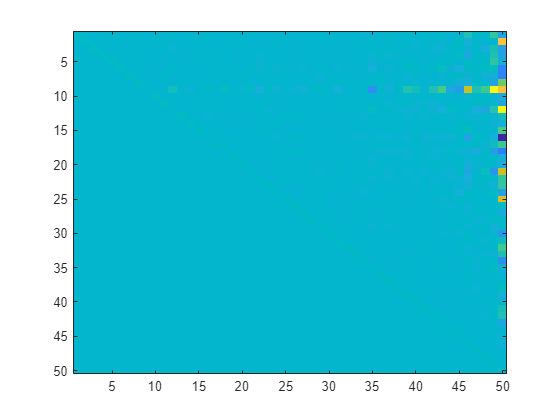

imagesc(logm(H))

A = Generate_Large_Matrix(500);
tic
A = Simple_QR(A,500);
toc

Elapsed time is 70.330954 seconds.


A

A = 1.0e+04 *

    0.0500   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0000   -0.0000   -0.0001    0.0001    0.0000   -0.0000   -0.0001    0.0001    0.0001    0.0001    0.0003   -0.0001    0.0002    0.0000   -0.0001   -0.0000    0.0002   -0.0002    0.0001   -0.0001    0.0002    0.0001    0.0001   -0.0002    0.0000    0.0001    0.0004   -0.0002   -0.0000   -0.0002    0.0002    0.0000    0.0000
   -0.0000    0.0498   -0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001   -0.0000    0.0000   -0.0000   -0.0001   -0.0001    0.0002   -0.0002    0.0001   -0.0000   -0.0001   -0.0000   -0.0001    0.0001    0.0000   -0.0001   -0.0002    0.0001    0.0001   -0.0001    0.0002   -0.0002    0.0000    0.0000    0.0001   -0.0002    0.0002   -0.0002    0.0000   -0.0001    0.0002   -0.0002    0.0003   -0.0001   -

A = Generate_Large_Matrix(500);
H = Householder_hessenberg(A);
tic
H = Unshifted_QR(H,1000);
toc

Elapsed time is 11.355365 seconds.


H

H = 1.0e+04 *

    0.0500   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0001    0.0001    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0001    0.0001    0.0000   -0.0002    0.0001   -0.0002    0.0001    0.0000    0.0001    0.0000   -0.0001    0.0000   -0.0000    0.0000   -0.0003   -0.0000   -0.0005   -0.0003    0.0001   -0.0002    0.0006    0.0005   -0.0000   -0.0002    0.0001    0.0002   -0.0002
   -0.0000    0.0498   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0001    0.0000    0.0000   -0.0001    0.0000    0.0001    0.0000   -0.0000   -0.0001   -0.0000    0.0001    0.0001    0.0001    0.0000   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001    0.0000    0.0002    0.0001   -0.0002   -0.0002   -0.0002    0.0001    0.0002    0.0001   -0.0001    0.0004   -0.0001   -0.0000    0.0003    0.0004    0.0001    0.0002    0.0003    

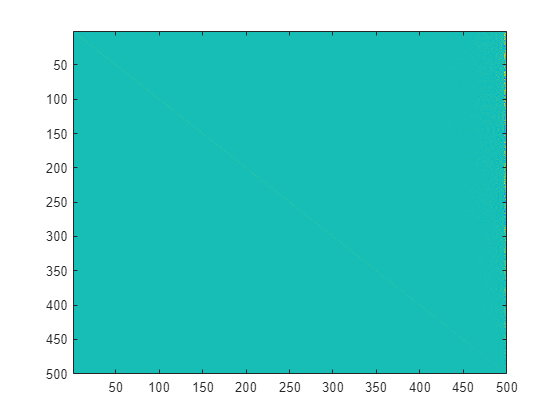

imagesc(logm(H))

A = Generate_Large_Matrix(500);
H = Householder_hessenberg(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 7.826206 seconds.


H

H = 1.0e+05 *

    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0000    0.0003   -0.0002    0.0001   -0.0000   -0.0000   -0.0000    0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0002   -0.0001   -0.0000    0.0001    0.0007   -0.0001    0.0000    0.0000    0.0005    0.0001
   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0004    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0001   -0.0001    0.0001    0.0002   -0.0001    0.0000    0.0000    0.0000   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0000   -0.0000   -0.0000   -0.0002   -0.0001   -0.0001    0.0000    

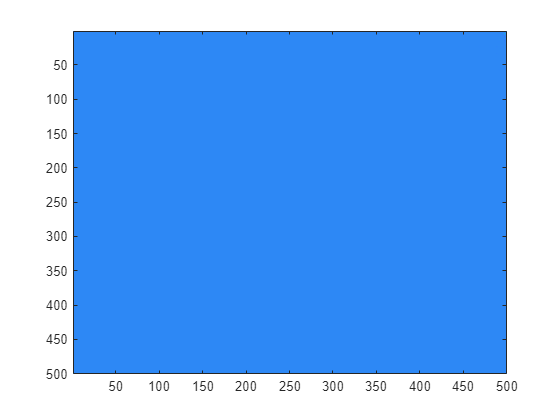

imagesc(logm(H))

A = Generate_Large_Matrix(500);
H = Householder_hessenberg(A);
tic
H = CHASE_THE_BULGE(H);
toc

Elapsed time is 1.727927 seconds.


H

H = 1.0e+06 *

    0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0005   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -

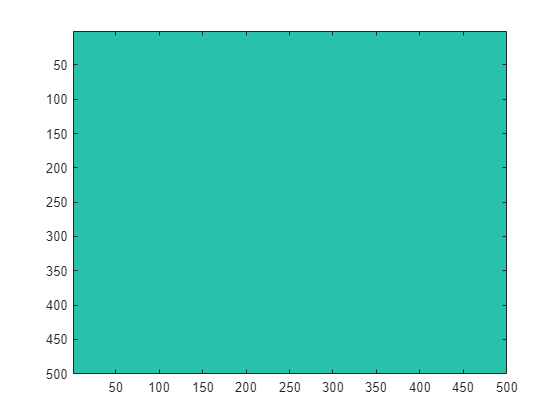

imagesc(H)

## Test velocità algoritmi

Speed_Tester(@Simple_QR, 50, false, 50, 100)

ans = 0.0227

Speed_Tester(@Simple_QR_mathlab, 50, false, 50, 100)

ans = 0.0085

Speed_Tester(@Simple_QR, 50, true, 50, 100)

ans = 0.0225

Speed_Tester(@Simple_QR_mathlab, 50, true, 50, 100)

ans = 0.0085

Speed_Tester(@Unshifted_QR, 50, true, 50, 100)

ans = 0.0152

Speed_Tester(@Shifted_QR, 0, true, 50, 100)

ans = 0.0099

Speed_Tester(@Shifted_QR_zero, 0, true, 50, 100)

ans = 0.0191

Speed_Tester(@CHASE_THE_BULGE, 0, true, 50, 100)

ans = 0.0103

## Implementazioni:

### Simple QR

function A = Simple_QR(A, max_iter)
    for i=1:max_iter
        [Q,R] = mgs(A);
        A = R*Q;
    end
end

%Simple QR algoritm functions, with Gram-Schmidt and with the built-in qr
%factorization
function A = Simple_QR_mathlab(A, max_iter)
    for i=1:max_iter
        [Q,R] = qr(A);
        A = R*Q;
    end
end

### Hessenberg Reduction

function A = Hessenberg_reduction(A)
    [num_rows, num_cols] = size(A);
    %itero sugli indici appena trovati
    for col=1:num_cols-1
        for row=num_cols:-1:2+col
            % trova gli indici della matrice di givens unando come pivot [col, col](sempre != 0)
            [c, s] = Givens_Rotation_Matrix_Entries(A(row-1, col), A(row, col));
            %si costruisce la matrice di givens partendo dall'identità
            G = eye(num_rows);
            %assegna gli indici trovati precedentemente alla matrice di givens
            G(row-1, row-1) = c;
            G(row, row) = c;
            G(row, row-1) = -s;
            G(row-1, row) = s;
            %annichilisce l'elemento in posizione A[row, col]
            A = G*A*G';
            if abs(A(row, col)) < 1.e-16
                A(row,col) = 0;
            end
        end
    end
end

%Generates the Givens Rotation matrix
function [c, s] = Givens_Rotation_Matrix_Entries(a, b)
    r = hypot(a,b);
    c = a/r;
    s = b/r;
end

### Hessenberg QR Unshifted:

function H = Unshifted_QR(H,max_iter)
    num_cols= length(H);
    %itero sugli indici appena trovati
    G = zeros(2);
    for i=1:max_iter
        for col=1:num_cols-1
            % trova gli indici della matrice di givens unando come pivot [col, col](sempre != 0)
            [c, s] = Givens_Rotation_Matrix_Entries(H(col, col), H(col+1, col));
            %si costruisce la matrice di givens partendo dall'identità
            %assegna gli indici trovati precedentemente alla matrice di givens
            G(1,1) = c;
            G(2,2) = c;
            G(2,1) = -s;
            G(1,2) = s;
            tmp{col} = G';
            %annichilisce l'elemento in posizione A[col+1, col]
            H(col:col+1,col:num_cols) = G*H(col:col+1,col:num_cols);
        end
        for col=1:num_cols-1
           H(1:col+1,col:col+1) = H(1:col+1,col:col+1)*tmp{col};
        end
    end
end

### Shifted QR

%QR algorithm using the last element of the diagonal as a Shift untill the
%element below the diagonal is zero
function H = Shifted_QR_zero(H)
    num_rows = length(H);
    for m=num_rows:-1:2
        while abs(H(m,m-1)) ~= 0
            [Q, R] = qr(H(1:m,1:m)-(H(m,m)*eye(m)));
            H(1:m,1:m) = (R*Q)+(H(m,m)*eye(m));
        end
    end
end

%QR algorithm using the last element of the diagonal as a Shift untill the
%element below the diagonal is small enough to be considered zero
function H = Shifted_QR(H)
    num_rows = length(H);
    for m=num_rows:-1:2
        while abs(H(m,m-1)) > 1e-15
            [Q, R] = qr(H(1:m,1:m)-(H(m,m)*eye(m)));
            H(1:m,1:m) = (R*Q)+(H(m,m)*eye(m));
        end
    end
end

### **Modified Gram-Schmidt**

%QR factorization using the Gram-Schmidt method
function [Q,R] =  mgs(X)
    [n,p] = size(X);
    Q = zeros(n,p);
    R = zeros(p,p);
    for k = 1:p
        Q(:,k) = X(:,k);
        for i = 1:k-1
            R(i,k) = Q(:,i)'*Q(:,k);
            Q(:,k) = Q(:,k) - R(i,k)*Q(:,i);
        end
        R(k,k) = norm(Q(:,k))';
        Q(:,k) = Q(:,k)/R(k,k);
    end
end

## HOUSEHOLDER FREESTYLE

%Transofrms an NxN matrix into it's Hessemberg form using the Householder
%reflectors
function H = Householder_hessenberg(A)
    n = length(A);
    for k=1:n-2
        tmp = A(k+1:n,k);
        tmp2 = norm(tmp');
        zer = zeros(1,n-k);
        zer(1) = 1;
        V1 = tmp' + tmp2*zer;
        c = 2/(V1*V1');
        P = eye(n-k) - c*(V1'*V1);
        A(k+1:n,k:n) = P*A(k+1:n,k:n);
        A(1:n,k+1:n) = A(1:n,k+1:n)*P';
    end
    H = A;
end

%Pure Magic
function H = CHASE_THE_BULGE(H)
    n = length(H);
    p = n;
    while p > 2
        q = p-1;
        s = H(q,q) + H(p,p);
        t = H(q,q)*H(p,p) - H(q,p)*H(p,q);
        x = H(1,1)*H(1,1) + H(1,2)*H(2,1) - s*H(1,1) + t;
        y = H(2,1)*(H(1,1) + H(2,2) - s);
        z = H(2,1)*H(3,2);

        for k=0:p-3
            P = reflector([x,y,z]);
            r = max(1,k);
            H(k+1:k+3,r:n) = P'*H(k+1:k+3,r:n);
            r = min(k+4,p);
            H(1:r,k+1:k+3) = H(1:r,k+1:k+3)*P;
            x = H(k+2,k+1);
            y = H(k+3,k+1);
            if k < p-3
                z = H(k+4,k+1);
            end
        end
        
        G = eye(2);
        [c, s] = Givens_Rotation_Matrix_Entries(x, y);
        G(1,1) = c;
        G(2,2) = c;
        G(2,1) = -s;
        G(1,2) = s;
        H(q:p,p-2:n) = G*H(q:p,p-2:n);
        H(1:p,p-1:p) = H(1:p,p-1:p)*G';
        %Check for convergence
        if abs(H(p,q)) < (1e-5 * (abs(H(q,q)) + abs(H(p,p))))
            H(p,q) = 0;
            p = p-1;
            q = p-1;
        elseif abs(H(p-1,q-1)) < (1e-5 * (abs(H(q-1,q-1)) + abs(H(q,q))))
            H(p-1,q-1) = 0;
            p = p-2;
            q = p-1;
        end
    end
end

%Generates the Householder reflector starting from a vector V of arbitraty
%size
function P = reflector(V)
    tmp2 = norm(V');
    zer = zeros(1,length(V));
    zer(1) = 1;
    V1 = V + tmp2*zer;
    c = 2/(V1*V1');
    P = eye(length(V)) - c*(V1'*V1);
end

%Function to generare NxN real matrix with real eigenvalues from 1 to N
function A = Generate_Large_Matrix(n)
    D = diag(1:n);
    S=rand(n); 
    S = (S - .5)*2;
    A = S*D/S;
end

%Function used to test the different implementations
function time = Speed_Tester(fun, max_iter_alg, hessemberg, matrix_dim, num_iter)
    time = 1:num_iter;
    for i=1:num_iter
        A = Generate_Large_Matrix(matrix_dim);
        if hessemberg
            A = Householder_hessenberg(A);
        end
        if max_iter_alg == 0
            tic
            fun(A);
            time(i) = toc;
        else
            tic
            fun(A, max_iter_alg);
            time(i) = toc;
        end
    end
    time = mean(time);
end